clear
clc
%
%chosing folder of data
%cd 'C:\Users\guilh\Desktop\Projetos\PapersEmAndamento\Carbon Tax\Scenarios'
cd 'D:\OneDrive - University of Pisa\PISA\carbon tax\EnergyEconomics';

% Import data
% Base = importdata('BASE.tab');
%BASELINE = importdata('..\Eurogreen_JRC\Baseline.tab');
Baseline = importdata('.\Baseline.tab');
CarbonTax = importdata('.\CarbonTax.tab');
Progressive = importdata('.\ProgressiveCarbonTax.tab');%threshold is 4 Ton
CTStructural = importdata('.\CarbonTaxStructural.tab');
ProgressiveStructural = importdata('.\ProgressiveCarbonTaxStructural.tab');

Baseline.data=Baseline.data;
CarbonTax.data=CarbonTax.data;
Progressive.data=Progressive.data;
CTStructural.data=CTStructural.data;
ProgressiveStructural.data=ProgressiveStructural.data; %necessario??

seed_baseline=Baseline.data(:,2);
variab_baseline= Baseline.textdata;
variab_baseline(1:2) = [];

year = 2010:2050; 
nyear = length(year);

year_plot=2023:2050; %Alterei o periodo Inicial
nyear_p=length(year_plot);


final=size(variab_baseline,2); %Conferir dimensao

lista = variab_baseline(1:nyear:final);
lista=string(lista);
lista = erase(lista,"T0 "); %erases time in the name of the variable
%clear variab_baseline
%nreal = length(2014:2019);
clc
clo = [0.1,0.1,0.1; 0.05, 0.4, 0.05; 0.64,0.08,0.21; 0.05, 0.45, 0.75;...
       0.3,0.3,0.3;  0.80, 0.95, 0.80; 0.95, 0.75, 0.75;0.60, 0.90, 0.90 ];


## Baseline and Scenarios Analysis

   
%%plotting variable belonging to dataset
plotVariables={'average hourly real wage','average hourly wage','debt gdp','def gdp','e','GDP real','gini emissions','inflation','total emissions','u','yd hh gini','yd hh gini after tls'};
labelVariables={'Av Real Wage (€ 2010)','Av Nominal Wage (€)','Debt-to-GDP (%)','Deficit-to-GDP','Employment rate (%)','GDP (€ bn)','Gini Coefficient of Emissions','Inflation (%)','GHG Emissions (MT CO2Eq)','Unemployment Rate (%)','Gini Coefficient Pre-Tax','Gini Coefficient'};

labelVariables_Diff={'Av Real Wage (€ 2010)','Av Nominal Wage (€)','Debt-to-GDP (p.p.)','Deficit-to-GDP','Employment rate (p.p.)','GDP (%)','Gini Coefficient of Emissions','Inflation (p.p.)','GHG Emissions (MT CO2Eq)','Unemployment Rate (%)','Gini Coefficient Pre-Tax','Gini Coefficient'};
%checar Unidades.
unitstransformation=[1,1,100,100,100,1/1000000000,100,100,1,100,100,100];%%YET TO ADJUST GDP %% AND TOTAL EMISSIONS
Scenarios={'Baseline','Carbon Tax','Progressive CT','CT Struct.','Progressive CT Struct.'};
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
niter = size(Baseline.data,1); l = length(Scenarios);
l1=l-1 %Policy Scenarios for deviation 

l1 = 4

title_graph= strings(0);
title_graph_Diff= strings(0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

k=6;
variavel=plotVariables{k}

variavel = 'GDP real'

title_graph(1)=labelVariables{k};
title_graph_Diff(1)=labelVariables_Diff{k};
x = find(lista==variavel);
in = (x-1)*nyear+1+15; 
fn = x*nyear+2; %Alterei para 2023
A = zeros(niter, nyear_p, l);
    A(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    A(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    A(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    A(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    A(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;

matrix_A = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = A(:,:, i);
    matrix_A(i,:) = median(s,"omitnan");
    matrix_A(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (For GDP we use relative differences).

A1 = zeros(niter, nyear_p, l1);
    A1(:,:,1)=100*(A(:,:,2)-A(:,:,1))./A(:,:,1);
    A1(:,:,2)=100*(A(:,:,3)-A(:,:,1))./A(:,:,1);
    A1(:,:,3)=100*(A(:,:,4)-A(:,:,1))./A(:,:,1);
    A1(:,:,4)=100*(A(:,:,5)-A(:,:,1))./A(:,:,1);

matrix_A_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = A1(:,:, i);
    matrix_A_deviation(i,:) = median(s,"omitnan");
    matrix_A_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear variavel x s k

k=5;
variavel=plotVariables{k}

variavel = 'e'

title_graph(2)=labelVariables{k};
title_graph_Diff(2)=labelVariables_Diff{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2; %Alterei para 2023
B = zeros(niter, nyear_p, l);
    B(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    B(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    B(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    B(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    B(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;

matrix_B = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = B(:,:, i);
    matrix_B(i,:) = median(s,"omitnan");
    matrix_B(i+l,:) = 1*mad(s,1);
end
%% Deviations from the Baseline (For employment rate we use absolute differences).

B1 = zeros(niter, nyear_p, l1);
    B1(:,:,1)=(B(:,:,2)-B(:,:,1));
    B1(:,:,2)=(B(:,:,3)-B(:,:,1));
    B1(:,:,3)=(B(:,:,4)-B(:,:,1));
    B1(:,:,4)=(B(:,:,5)-B(:,:,1));

matrix_B_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = B1(:,:, i);
    matrix_B_deviation(i,:) = median(s,"omitnan");
    matrix_B_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear variavel x s k
%new variable
k=3;
variavel=plotVariables{k}

variavel = 'debt gdp'

title_graph(3)=labelVariables{k};
title_graph_Diff(3)=labelVariables_Diff{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2;%Alterei para 2023
C = zeros(niter, nyear_p, l);
    C(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    C(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    C(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    C(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    C(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;
    
matrix_C = zeros(l,nyear_p);
for i = 1:l
    s = C(:,:, i);
    matrix_C(i,:) = median(s,"omitnan");
    matrix_C(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (For Debt-to-GDP we use absolute differences).

C1 = zeros(niter, nyear_p, l1);
    C1(:,:,1)=(C(:,:,2)-C(:,:,1));
    C1(:,:,2)=(C(:,:,3)-C(:,:,1));
    C1(:,:,3)=(C(:,:,4)-C(:,:,1));
    C1(:,:,4)=(C(:,:,5)-C(:,:,1));

matrix_C_deviation = zeros(l1,nyear_p);
for i = 1:l1
    s = C1(:,:, i);
    matrix_C_deviation(i,:) = median(s,"omitnan");
    matrix_C_deviation(i+l1,:) = 2*mad(s,1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear variavel x s k
k=8;
variavel=plotVariables{k}

variavel = 'inflation'

title_graph(4)=labelVariables{k};
title_graph_Diff(4)=labelVariables_Diff{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2;%Alterei para 2023
D = zeros(niter, nyear_p, l);
    D(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    D(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    D(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    D(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    D(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;
   
matrix_D = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = D(:,:, i);
    matrix_D(i,:) = median(s,"omitnan");
    matrix_D(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (For Debt-to-GDP we use absolute differences).

D1 = zeros(niter, nyear_p, l1);
    D1(:,:,1)=(D(:,:,2)-D(:,:,1));
    D1(:,:,2)=(D(:,:,3)-D(:,:,1));
    D1(:,:,3)=(D(:,:,4)-D(:,:,1));
    D1(:,:,4)=(D(:,:,5)-D(:,:,1));

matrix_D_deviation = zeros(l1,nyear_p);
for i = 1:l1
    s = D1(:,:, i);
    matrix_D_deviation(i,:) = median(s,"omitnan");
    matrix_D_deviation(i+l1,:) = 2*mad(s,1);
end


## MacroVariables Scenario Figures Diff. w.r.t. Baseline


%% Computing diff w.r.t. baseline
figure;
figure01=tiledlayout(2,2)

figure01 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


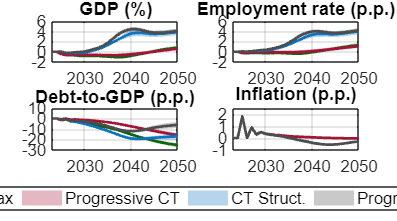


nexttile
for i = 1:l1      
 h(i) = plot(year_plot, matrix_A_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_A_deviation(i,:) + matrix_A_deviation(i+l1,:) fliplr(matrix_A_deviation(i,:) - matrix_A_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none') 
 hold on 
end
xlim([2023,2050]);
ylim([-2,6])
yticks=(-5:1:5);
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
t1=title(title_graph_Diff(1));
t1.Position=t1.Position+0.25;    
hold off


nexttile
for i = 1:l1      
 h(i) = plot(year_plot, matrix_B_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_B_deviation(i,:) + matrix_B_deviation(i+l1,:) fliplr(matrix_B_deviation(i,:) - matrix_B_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none') 
 hold on
end
xlim([2023,2050]);
ylim([-2,6])
yticks=(-1:1:5);
set(gca,'FontSize',12.5,'FontWeight','normal'); 
t2=title(title_graph_Diff(2));
t2.Position(2) = t2.Position(2) + 0.25; % Adjust the vertical position
hold off

nexttile 
for i = 1:l1      
 h(i) = plot(year_plot, matrix_C_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_C_deviation(i,:) + matrix_C_deviation(i+l1,:) fliplr(matrix_C_deviation(i,:) - matrix_C_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none') 
 hold on
end
xlim([2023,2050]);
ylim([-30,10])
yticks=(-5:0.5:5);
set(gca,'FontSize',12.5,'FontWeight','normal'); 
t3=title(title_graph_Diff(3));
t3.Position(2) = t3.Position(2) + 0.1; % Adjust the vertical position
hold off

nexttile
for i = 1:l1      
 h(i) = plot(year_plot, matrix_D_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_D_deviation(i,:) + matrix_D_deviation(i+l1,:) fliplr(matrix_D_deviation(i,:) - matrix_D_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none') 
hold on
end
xlim([2023,2050]);
ylim([-1,2.5])
yticks=(-5:1:5);%%
set(gca,'FontSize',12.5,'FontWeight','normal'); 
t4=title(title_graph_Diff(4));%, 'Interpreter','tex','FontName','ZapfDingbats'
t4.Position(2) = t4.Position(2)+0.25; % Adjust the vertical position
hold off

% Create common legend
lgd = legend(Scenarios(2:5), 'Orientation', 'horizontal','FontSize',12.5);
% Move the legend below the plots
lgd.Layout.Tile = 'south';

x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);

saveas(gcf,'Figure01.jpg')


clear t1 t2 t3 t4


## MacroVariables Scenario Figures 

%%Figures of the Baseline + 3 policy scenarios

figure;
figure02=tiledlayout(2,2)

figure02 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


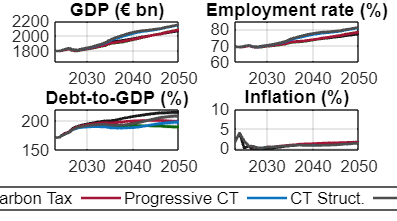

nexttile

for i = 1:l
       
 h(i) = plot(year_plot, matrix_A(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_A(i,:) + matrix_A(i+l,:) fliplr(matrix_A(i,:) - matrix_A(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_A(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:2:10);%%
ylim([1650,2200]);%%
xlim([2023,2050]);
t1=title(title_graph(1));%,'Position','bottom'
t1.Position(2) = t1.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_B(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_B(i,:) + matrix_B(i+l,:) fliplr(matrix_B(i,:) - matrix_B(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_B(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:5:100);%%
ylim([60,85]);%%
xlim([2023,2050]);
t2=title(title_graph(2));
t2.Position(2) = t2.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_C(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_C(i,:) + matrix_C(i+l,:) fliplr(matrix_C(i,:) - matrix_C(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_C(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:1:100);%%
ylim([150,220]);%%
xlim([2023,2050]);
t3=title(title_graph(3));
t3.Position(2) = t3.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_D(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_D(i,:) + matrix_D(i+l,:) fliplr(matrix_D(i,:) - matrix_D(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_D(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(1000:100:2000);%%
ylim([-0.5,10]);%%
xlim([2023,2050]);
t4=title(title_graph(4));%, 'Interpreter','tex','FontName','ZapfDingbats'
t4.Position(2) = t4.Position(2) + 0.25; % Adjust the vertical position
hold off


% Create common legend
lgd = legend(h(1:5),Scenarios, 'Orientation', 'horizontal','FontSize',12.5);
% Move the legend below the plots
lgd.Layout.Tile = 'south';
x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);
saveas(gcf,'Figure02.jpg')


clear t1 t2 t3 t4

## Emissions+Inequality Scenario Figures Diff. w.r.t. Baseline

%%Recreating Matrices
clear matrix_A matrix_B matrix_C matrix_D matrix_A_deviation matrix_B_deviation matrix_C_deviation matrix_D_deviation A B C D A1 B1 C1 D1

k=9; %Emissions
variavel=plotVariables{k}

variavel = 'total emissions'

title_graph(1)=labelVariables{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2; %Adjusted to Start 2023
A = zeros(niter, nyear_p, l);
    A(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    A(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    A(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    A(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    A(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;

matrix_A = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = A(:,:, i);
    matrix_A(i,:) = median(s,"omitnan");
    matrix_A(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (we use relative differences).

A1 = zeros(niter, nyear_p, l1);
    A1(:,:,1)=100*(A(:,:,2)-A(:,:,1))./A(:,:,1);
    A1(:,:,2)=100*(A(:,:,3)-A(:,:,1))./A(:,:,1);
    A1(:,:,3)=100*(A(:,:,4)-A(:,:,1))./A(:,:,1);
    A1(:,:,4)=100*(A(:,:,5)-A(:,:,1))./A(:,:,1);

matrix_A_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = A1(:,:, i);
    matrix_A_deviation(i,:) = median(s,"omitnan");
    matrix_A_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear variavel x s k

k=7; % Gini Emissions
variavel=plotVariables{k}

variavel = 'gini emissions'

title_graph(2)=labelVariables{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2; %Adjusted to start 2023
B = zeros(niter, nyear_p, l);
    B(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    B(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    B(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    B(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    B(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;

matrix_B = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = B(:,:, i);
    matrix_B(i,:) = median(s,"omitnan");
    matrix_B(i+l,:) = 1*mad(s,1);
end
%% Deviations from the Baseline (For employment rate we use absolute differences).

B1 = zeros(niter, nyear_p, l1);
    B1(:,:,1)=(B(:,:,2)-B(:,:,1));
    B1(:,:,2)=(B(:,:,3)-B(:,:,1));
    B1(:,:,3)=(B(:,:,4)-B(:,:,1));
    B1(:,:,4)=(B(:,:,5)-B(:,:,1));

matrix_B_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = B1(:,:, i);
    matrix_B_deviation(i,:) = median(s,"omitnan");
    matrix_B_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear variavel x s k
%new variable
k=12; %Gini after tls
variavel=plotVariables{k}

variavel = 'yd hh gini after tls'

title_graph(3)=labelVariables{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2; %Adjusted to start 2023
C = zeros(niter, nyear_p, l);
    C(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    C(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    C(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    C(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    C(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;
    
matrix_C = zeros(l,nyear_p);
for i = 1:l
    s = C(:,:, i);
    matrix_C(i,:) = median(s,"omitnan");
    matrix_C(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (For Debt-to-GDP we use absolute differences).

C1 = zeros(niter, nyear_p, l1);
    C1(:,:,1)=(C(:,:,2)-C(:,:,1));
    C1(:,:,2)=(C(:,:,3)-C(:,:,1));
    C1(:,:,3)=(C(:,:,4)-C(:,:,1));
    C1(:,:,4)=(C(:,:,5)-C(:,:,1));

matrix_C_deviation = zeros(l1,nyear_p);
for i = 1:l1
    s = C1(:,:, i);
    matrix_C_deviation(i,:) = median(s,"omitnan");
    matrix_C_deviation(i+l1,:) = 2*mad(s,1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear variavel x s k
k=7; %Gini of emissions
variavel=plotVariables{k}

variavel = 'gini emissions'

title_graph(4)=labelVariables{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2; %% Adjusted to start 2023
D = zeros(niter, nyear_p, l);
    D(:,:, 1) = unitstransformation(k)*Baseline.data(:, in:fn) ;
    D(:,:, 2) = unitstransformation(k)*CarbonTax.data(:, in:fn) ;
    D(:,:, 3) = unitstransformation(k)*Progressive.data(:, in:fn);
    D(:,:, 4) = unitstransformation(k)*CTStructural.data(:, in:fn) ;
    D(:,:, 5) = unitstransformation(k)*ProgressiveStructural.data(:, in:fn) ;
   
matrix_D = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = D(:,:, i);
    matrix_D(i,:) = median(s,"omitnan");
    matrix_D(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (For Debt-to-GDP we use absolute differences).

D1 = zeros(niter, nyear_p, l1);
    D1(:,:,1)=(D(:,:,2)-D(:,:,1));
    D1(:,:,2)=(D(:,:,3)-D(:,:,1));
    D1(:,:,3)=(D(:,:,4)-D(:,:,1));
    D1(:,:,4)=(D(:,:,5)-D(:,:,1));

matrix_D_deviation = zeros(l1,nyear_p);
for i = 1:l1
    s = D1(:,:, i);
    matrix_D_deviation(i,:) = median(s,"omitnan");
    matrix_D_deviation(i+l1,:) = 2*mad(s,1);
end




%% Computing diff w.r.t. baseline
figure;
figure1=tiledlayout(1,2)

figure1 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


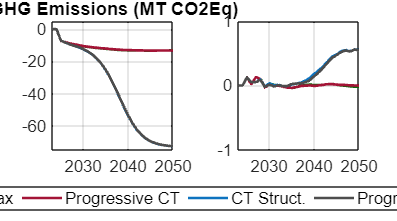


nexttile
for i = 1:l1      
 h(i) = plot(year_plot, matrix_A_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
hold on
% set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
% patch([year fliplr(year)], [matrix_D(i,:) + matrix_D(i+l,:) fliplr(matrix_D(i,:) - matrix_D(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
end
xlim([2023,2050]);
ylim([-75,5])
yticks=(-5:1:5);
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
t1=title(title_graph(1));
t1.Position=t1.Position+0.25;    
hold off

nexttile
for i = 1:l1      
 h(i) = plot(year_plot, matrix_B_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
hold on
end
xlim([2023,2050]);
ylim([-1,1])
yticks=(-1:1:5);
set(gca,'FontSize',12.5,'FontWeight','normal'); 
t2=title(title_graph(2));
t2.Position(2) = t2.Position(2) + 0.25; % Adjust the vertical position
hold off

% Create common legend
lgd = legend(Scenarios(2:5), 'Orientation', 'horizontal','FontSize',12.5);
% Move the legend below the plots
lgd.Layout.Tile = 'south';

x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);

saveas(gcf,'ScenariosDiff.jpg')


figure;
figure2=tiledlayout(1,2)

figure2 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


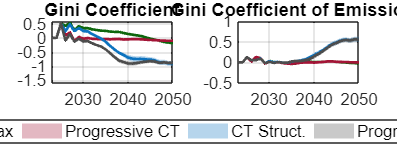

nexttile 
for i = 1:l1      
 h(i) = plot(year_plot, matrix_C_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_C_deviation(i,:) + matrix_C_deviation(i+l1,:) fliplr(matrix_C_deviation(i,:) - matrix_C_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none')   
 hold on
end
xlim([2023,2050]);
ylim([-1.6,0.6])
yticks=(-1.6:0.2:2);
set(gca,'FontSize',12.5,'FontWeight','normal'); 
t3=title(title_graph(3));
t3.Position(2) = t3.Position(2) ; %+ 0.1 Adjust the vertical position
hold off

nexttile
for i = 1:l1      
 h(i) = plot(year_plot, matrix_D_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_D_deviation(i,:) + matrix_D_deviation(i+l1,:) fliplr(matrix_D_deviation(i,:) - matrix_D_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none')   
 
 hold on
end
xlim([2023,2050]);
ylim([-0.5,1])
yticks=(-0.5:0.1:1);%%
set(gca,'FontSize',12.5,'FontWeight','normal'); 
t4=title(title_graph(4));%, 'Interpreter','tex','FontName','ZapfDingbats'
t4.Position(2) = t4.Position(2) ; %+ 0.1 Adjust the vertical position
hold off

% Create common legend
lgd = legend(Scenarios(2:5), 'Orientation', 'horizontal','FontSize',12.5);
% Move the legend below the plots
lgd.Layout.Tile = 'south';

x0=20;
y0=20;
width=900;%550
height=350;
set(gcf,'position',[x0,y0,width,height]);

saveas(gcf,'FigureGini.jpg')


clear t1 t2 t3 t4


## Emissions+Inequality Variables Scenario Figures 

%%Figures of the Baseline + 3 policy scenarios

tiledlayout(1,2)
nexttile

for i = 1:l
       
 h(i) = plot(year_plot, matrix_A(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_A(i,:) + matrix_A(i+l,:) fliplr(matrix_A(i,:) - matrix_A(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_A(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:2:10);%%
ylim([1650,2200]);%%
xlim([2023,2050]);
t1=title(title_graph(1));%,'Position','bottom'
t1.Position(2) = t1.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_B(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_B(i,:) + matrix_B(i+l,:) fliplr(matrix_B(i,:) - matrix_B(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_B(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:5:100);%%
ylim([60,85]);%%
xlim([2023,2050]);
t2=title(title_graph(2));
t2.Position(2) = t2.Position(2) + 0.25; % Adjust the vertical position
hold off
% Create common legend
lgd = legend(h(1:5),Scenarios, 'Orientation', 'horizontal','FontSize',12.5);
% Move the legend below the plots
lgd.Layout.Tile = 'south';
x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);
saveas(gcf,'Scenarios.jpg')




tiledlayout(1,2)
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_C(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_C(i,:) + matrix_C(i+l,:) fliplr(matrix_C(i,:) - matrix_C(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_C(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:1:100);%%
ylim([25,35]);%%
xlim([2023,2050]);
t3=title(title_graph(3));
t3.Position(2) = t3.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_D(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_D(i,:) + matrix_D(i+l,:) fliplr(matrix_D(i,:) - matrix_D(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_D(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(1000:100:2000);%%
ylim([0,30]);%%
xlim([2023,2050]);
t4=title(title_graph(4));%, 'Interpreter','tex','FontName','ZapfDingbats'
t4.Position(2) = t4.Position(2) + 0.25; % Adjust the vertical position
hold off


% Create common legend
lgd = legend(h(1:4),Scenarios, 'Orientation', 'horizontal','FontSize',12.5);

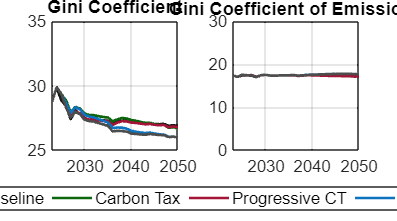

% Move the legend below the plots
lgd.Layout.Tile = 'south';

x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);
%saveas(gcf,'Scenarios.jpg')

clear t1 t2 t3 t4


## Kaya Identity Figures

clear A B C D matrix_A matrix_B matrix_C matrix_D matrix_A_deviation matrix_B_deviation matrix_C_deviation matrix_D_deviation A B C D A1 B1 C1 D1


%%Figures of the KAYA IDENTITY WITH BASELINE + 3 policy scenarios

plotVariablesKaya={'total emissions','GDPpc real decomp','NRG intensity decomp','Emissions intensity decomp','GHG decomp'};
labelVariablesKaya={'GHG Emissions (millions MT CO2Eq)','Per capita real GDP','Energy intensity','Emissions intensity','Emissions decomposition'};
unitsGHG=1/1000000; %MILLIOS OF metric tons of carbon dioxide

k=1;
variavel=plotVariablesKaya{k}

variavel = 'total emissions'

title_graph(1)=labelVariablesKaya{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2;%Alterei para 2023
A2 = zeros(niter, nyear_p, l);
    A2(:,:, 1) = unitsGHG*Baseline.data(:, in:fn) ;
    A2(:,:, 2) = unitsGHG*CarbonTax.data(:, in:fn) ;
    A2(:,:, 3) = unitsGHG*Progressive.data(:, in:fn);
    A2(:,:, 4) = unitsGHG*CTStructural.data(:, in:fn) ;
    A2(:,:, 5) = unitsGHG*ProgressiveStructural.data(:, in:fn) ;

matrix_A2 = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = A2(:,:, i);
    matrix_A2(i,:) = median(s,"omitnan");
    matrix_A2(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (Relative differences).

A20 = zeros(niter, nyear_p, l1);
    A20(:,:,1)=100*(A2(:,:,2)-A2(:,:,1))./A2(:,:,1);
    A20(:,:,2)=100*(A2(:,:,3)-A2(:,:,1))./A2(:,:,1);
    A20(:,:,3)=100*(A2(:,:,4)-A2(:,:,1))./A2(:,:,1);
    A20(:,:,4)=100*(A2(:,:,5)-A2(:,:,1))./A2(:,:,1);

matrix_A2_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = A20(:,:, i);
    matrix_A2_deviation(i,:) = median(s,"omitnan");
    matrix_A2_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


clear variavel x s k A2 A20

k=2;
variavel=plotVariablesKaya{k}

variavel = 'GDPpc real decomp'

title_graph(2)=labelVariablesKaya{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2;%Alterei para 2023
B2 = zeros(niter, nyear_p, l);
    B2(:,:, 1) = Baseline.data(:, in:fn) ;
    B2(:,:, 2) = CarbonTax.data(:, in:fn) ;
    B2(:,:, 3) = Progressive.data(:, in:fn);
    B2(:,:, 4) = CTStructural.data(:, in:fn) ;
    B2(:,:, 5) = ProgressiveStructural.data(:, in:fn) ;

matrix_B2 = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = B2(:,:, i);
    matrix_B2(i,:) = median(s,"omitnan");
    matrix_B2(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (Relative differences).

B20 = zeros(niter, nyear_p, l1);
    B20(:,:,1)=100*(B2(:,:,2)-B2(:,:,1))./B2(:,:,1);
    B20(:,:,2)=100*(B2(:,:,3)-B2(:,:,1))./B2(:,:,1);
    B20(:,:,3)=100*(B2(:,:,4)-B2(:,:,1))./B2(:,:,1);
    B20(:,:,4)=100*(B2(:,:,5)-B2(:,:,1))./B2(:,:,1);

matrix_B2_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = B20(:,:, i);
    matrix_B2_deviation(i,:) = median(s,"omitnan");
    matrix_B2_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


clear variavel x s k

k=3;
variavel=plotVariablesKaya{k}

variavel = 'NRG intensity decomp'

title_graph(3)=labelVariablesKaya{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2;%Alterei para 2023
C2 = zeros(niter, nyear_p, l);
    C2(:,:, 1) = Baseline.data(:, in:fn) ;
    C2(:,:, 2) = CarbonTax.data(:, in:fn) ;
    C2(:,:, 3) = Progressive.data(:, in:fn);
    C2(:,:, 4) = CTStructural.data(:, in:fn) ;
    C2(:,:, 5) = ProgressiveStructural.data(:, in:fn) ;
    
matrix_C2 = zeros(l,nyear_p);
for i = 1:l
    s = C2(:,:, i);
    matrix_C2(i,:) = median(s,"omitnan");
    matrix_C2(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (Relative differences).

C20 = zeros(niter, nyear_p, l1);
    C20(:,:,1)=100*(C2(:,:,2)-C2(:,:,1))./C2(:,:,1);
    C20(:,:,2)=100*(C2(:,:,3)-C2(:,:,1))./C2(:,:,1);
    C20(:,:,3)=100*(C2(:,:,4)-C2(:,:,1))./C2(:,:,1);
    C20(:,:,4)=100*(C2(:,:,5)-C2(:,:,1))./C2(:,:,1);

matrix_C2_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = C20(:,:, i);
    matrix_C2_deviation(i,:) = median(s,"omitnan");
    matrix_C2_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



clear variavel x s k C20 C2
k=4;
variavel=plotVariablesKaya{k}

variavel = 'Emissions intensity decomp'

title_graph(4)=labelVariablesKaya{k};
x = find (lista==variavel);
in = (x-1)*nyear+1+15; fn = x*nyear+2;%Alterei para 2023
D2 = zeros(niter, nyear_p, l);
    D2(:,:, 1) = Baseline.data(:, in:fn) ;
    D2(:,:, 2) = CarbonTax.data(:, in:fn) ;
    D2(:,:, 3) = Progressive.data(:, in:fn);
    D2(:,:, 4) = CTStructural.data(:, in:fn) ;
    D2(:,:, 5) = ProgressiveStructural.data(:, in:fn) ;
   
matrix_D2 = zeros(l,nyear_p);
for i = 1:l
    %mean
    s = D2(:,:, i);
    matrix_D2(i,:) = median(s,"omitnan");
    matrix_D2(i+l,:) = 1*mad(s,1);
end

%% Deviations from the Baseline (Relative differences).

D20 = zeros(niter, nyear_p, l1);
    D20(:,:,1)=100*(D2(:,:,2)-D2(:,:,1))./D2(:,:,1);
    D20(:,:,2)=100*(D2(:,:,3)-D2(:,:,1))./D2(:,:,1);
    D20(:,:,3)=100*(D2(:,:,4)-D2(:,:,1))./D2(:,:,1);
    D20(:,:,4)=100*(D2(:,:,5)-D2(:,:,1))./D2(:,:,1);

matrix_D2_deviation = zeros(l1,nyear_p);
for i = 1:l1
    %mean
    s = D20(:,:, i);
    matrix_D2_deviation(i,:) = median(s,"omitnan");
    matrix_D2_deviation(i+l1,:) = 2*mad(s,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;
figure10=tiledlayout(2,2)

figure10 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


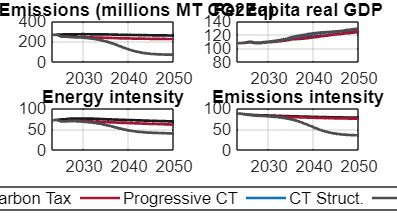

nexttile

for i = 1:l
       
 h(i) = plot(year_plot, matrix_A2(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_A2(i,:) + matrix_A2(i+l,:) fliplr(matrix_A2(i,:) - matrix_A2(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_A(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:2:10);%%
ylim([0,400]);%%
xlim([2023,2050]);
t1=title(title_graph(1));%,'Position','bottom'
t1.Position(2) = t1.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_B2(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_B2(i,:) + matrix_B2(i+l,:) fliplr(matrix_B2(i,:) - matrix_B2(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_B(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(75:5:150);%%
ylim([80,140]);%%
xlim([2023,2050]);
t2=title(title_graph(2));
t2.Position(2) = t2.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_C2(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_C2(i,:) + matrix_C2(i+l,:) fliplr(matrix_C2(i,:) - matrix_C2(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_C(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(70:5:150);%%
ylim([0,100]);%%
xlim([2023,2050]);
t3=title(title_graph(3));
t3.Position(2) = t3.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l      
 h(i) = plot(year_plot, matrix_D2(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_D2(i,:) + matrix_D2(i+l,:) fliplr(matrix_D2(i,:) - matrix_D2(i+l,:))], clo(i,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_D(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(75:5:150);%%
ylim([0,100]);%%
xlim([2023,2050]);
t4=title(title_graph(4));%, 'Interpreter','tex','FontName','ZapfDingbats'
t4.Position(2) = t4.Position(2) + 0.25; % Adjust the vertical position
hold off


% Create common legend
lgd = legend(h(1:5),Scenarios, 'Orientation', 'horizontal','FontSize',12.5);
% Move the legend below the plots
lgd.Layout.Tile = 'south';
x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);
saveas(gcf,'KayaIdentity.jpg')


clear t1 t2 t3 t4



## Kaya figures as deviation from baseline


figure;
figure20=tiledlayout(2,2)

figure20 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


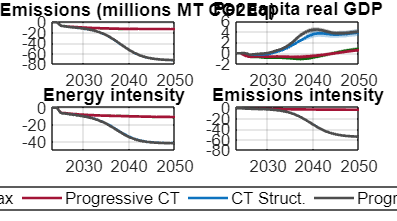

nexttile

for i = 1:l1
       
 h(i) = plot(year_plot, matrix_A2_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_A2_deviation(i,:) + matrix_A2_deviation(i+l1,:) fliplr(matrix_A2_deviation(i,:) - matrix_A2_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_A(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(-20:2:10);%%
ylim([-80,2]);%%
xlim([2023,2050]);
t1=title(title_graph(1));%,'Position','bottom'
t1.Position(2) = t1.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l1      
 h(i) = plot(year_plot, matrix_B2_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_B2_deviation(i,:) + matrix_B2_deviation(i+l1,:) fliplr(matrix_B2_deviation(i,:) - matrix_B2_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_B(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(-20:2:10);%%
ylim([-2,6]);%%
xlim([2023,2050]);
t2=title(title_graph(2));
t2.Position(2) = t2.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l1      
 h(i) = plot(year_plot, matrix_C2_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_C2_deviation(i,:) + matrix_C2_deviation(i+l1,:) fliplr(matrix_C2_deviation(i,:) - matrix_C2_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_C(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(-20:2:10);%%
ylim([-50,2]);%%
xlim([2023,2050]);
t3=title(title_graph(3));
t3.Position(2) = t3.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

for i = 1:l1      
 h(i) = plot(year_plot, matrix_D2_deviation(i,:), 'LineStyle','-','LineWidth', 2,'Color',clo(i+1,:)); hold on; grid on;
 set(get(get(h(i),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
 patch([year_plot fliplr(year_plot)], [matrix_D2_deviation(i,:) + matrix_D2_deviation(i+l1,:) fliplr(matrix_D2_deviation(i,:) - matrix_D2_deviation(i+l1,:))], clo(i+1,:),'FaceAlpha',0.3, 'EdgeColor','none')   
hold on
end
%plot(year, matrix_D(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(-20:2:10);%%
ylim([-80,4]);%%
xlim([2023,2050]);
t4=title(title_graph(4));%, 'Interpreter','tex','FontName','ZapfDingbats'
t4.Position(2) = t4.Position(2) + 0.25; % Adjust the vertical position
hold off


% Create common legend
lgd = legend(h(1:4),Scenarios(2:5), 'Orientation', 'horizontal','FontSize',12.5);
% Move the legend below the plots
lgd.Layout.Tile = 'south';
x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);
saveas(gcf,'KayaDeviation.jpg')


clear t1 t2 t3 t4


%%Figures of the Baseline %% Some Problems...

tiledlayout(2,2)
nexttile

plot(year, matrix_A(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
patch([year_plot fliplr(year)], [matrix_A(1,:) + matrix_A(5,:) fliplr(matrix_A(1,:) - matrix_A(5,:))], clo(1,:),'FaceAlpha',0.3, 'EdgeColor','none');   
%hold on
%plot(validation_plot(1,:),validation_plot(3,:),'LineStyle','--','Color','r','LineWidth', 2)
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:2:10);%%
ylim([-0.5,10]);%%
xlim([2021,2030]);
t1=title(title_graph(1));%('Inflation Rate (%)');%,'Position','bottom'
t1.Position(2) = t1.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

plot(year, matrix_B(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
patch([year_plot fliplr(year)], [matrix_B(1,:) + matrix_B(5,:) fliplr(matrix_B(1,:) - matrix_B(5,:))], clo(1,:),'FaceAlpha',0.3, 'EdgeColor','none');  
%hold on
%plot(validation_plot(1,:),validation_plot(2,:),'LineStyle','--','Color','r','LineWidth', 2)
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:5:100);%%
ylim([90,105]);%%
xlim([2021,2030]);
t2=title('Average Real Wage (2021=100)');
t2.Position(2) = t2.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

plot(year, matrix_C(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
patch([year_plot fliplr(year)], [matrix_C(1,:) + matrix_C(5,:) fliplr(matrix_C(1,:) - matrix_C(5,:))], clo(1,:),'FaceAlpha',0.3, 'EdgeColor','none');  
%hold on
%plot(validation_plot(1,:),validation_plot(4,:),'LineStyle','--','Color','r','LineWidth', 2)
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(0:1:100);%%
ylim([55,70]);%%
xlim([2021,2030]);
t3=title('Employment Rate (%)');
t3.Position(2) = t3.Position(2) + 0.25; % Adjust the vertical position
hold off
nexttile

plot(year, matrix_D(1,:), 'LineStyle','-','LineWidth', 2,'Color','k'); grid on;%hold on; 
patch([year_plot fliplr(year)], [matrix_D(1,:) + matrix_D(5,:) fliplr(matrix_D(1,:) - matrix_D(5,:))], clo(1,:), 'FaceAlpha',0.3,'EdgeColor','none');  
%hold on
%plot(validation_plot(1,:),validation_plot(5,:),'LineStyle','--','Color','r','LineWidth', 2)
set(gca,'FontSize',12.5,'FontWeight','normal'); %axis([2014 2050 22 38]);
yticks=(1500:50:2000);%%
ylim([1500,1700]);%%
xlim([2021,2030]);
t4=title('Real GDP (Millions EUR)');%, 'Interpreter','tex','FontName','ZapfDingbats'
t4.Position(2) = t4.Position(2) + 0.25; % Adjust the vertical position
% hold off
%%%
%%Note
%% Trabalhar com 2021-2030, para evitar shocks do COVID

%%
x0=20;
y0=20;
width=900;%550
height=500;
set(gcf,'position',[x0,y0,width,height]);
saveas(gcf,'Baseline1.jpg')

clear t1 t2 t3 t4

medians_table=[matrix_A(1,:);matrix_B(1,:);matrix_C(1,:);matrix_D(1,:)]


writematrix(medians_table,'medians_table.xlsx')